load('proj7wordsData.mat');
load('proj7chordsData.mat');

[nRows, nCols, nTimes] = size(image_3d);
for time = 1:nTimes
    image_m = squeeze(image_3d(:, :, time));
    smoothImage_m = conv2(image_m, ones(4), 'same');
    image2_3d(:, :, time) = smoothImage_m;
    
    % Insert code here to display both the original and smoothed 
    % images (in one figure):
    if time == 1 
        figure
        subplot(1,2,1)
        imagesc(image_m)
        axis image
        subplot(1,2,2)
        imagesc(smoothImage_m)
        axis image
    end 
end

% Create head mask
% Use the magnitude of the first image to form a binary mask  
image_m = squeeze(image_3d(:, :, 1));
mask_m = (image_m > 0.1*max(image_m(:))); % set mask at higher threshold 
figure
imagesc(mask_m)
colormap(gray)
axis image
axis off
title('Head mask')

% normalize by L2 norm
meanNormalized = (sound_v - mean(sound_v));
normSound_v = meanNormalized./norm(meanNormalized,2);

% v = 1:5;
% subteract = (v - mean(v))
% N = subteract./norm(subteract,2)
% mean(N)
% sqrt(sum(N.^2))

rWord_m = zeros(nRows, nCols);

for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            data_v = squeeze(image2_3d(row, col, :));
            % Insert code here to transform the data_v to have zero mean 
            % and unit norm.  Call this vector 
            meanNormalized = (data_v - mean(data_v));
            normData_v = meanNormalized./norm(meanNormalized,2);

            % Calculate the correlation coefficient of normData_v and 
            % normSound_v:
            rWord_m(row, col) = sum(normData_v.* normSound_v);
        end
    end
end 
figure
imagesc(rWord_m)
colorbar
title('Correlation Coefficient matrix')

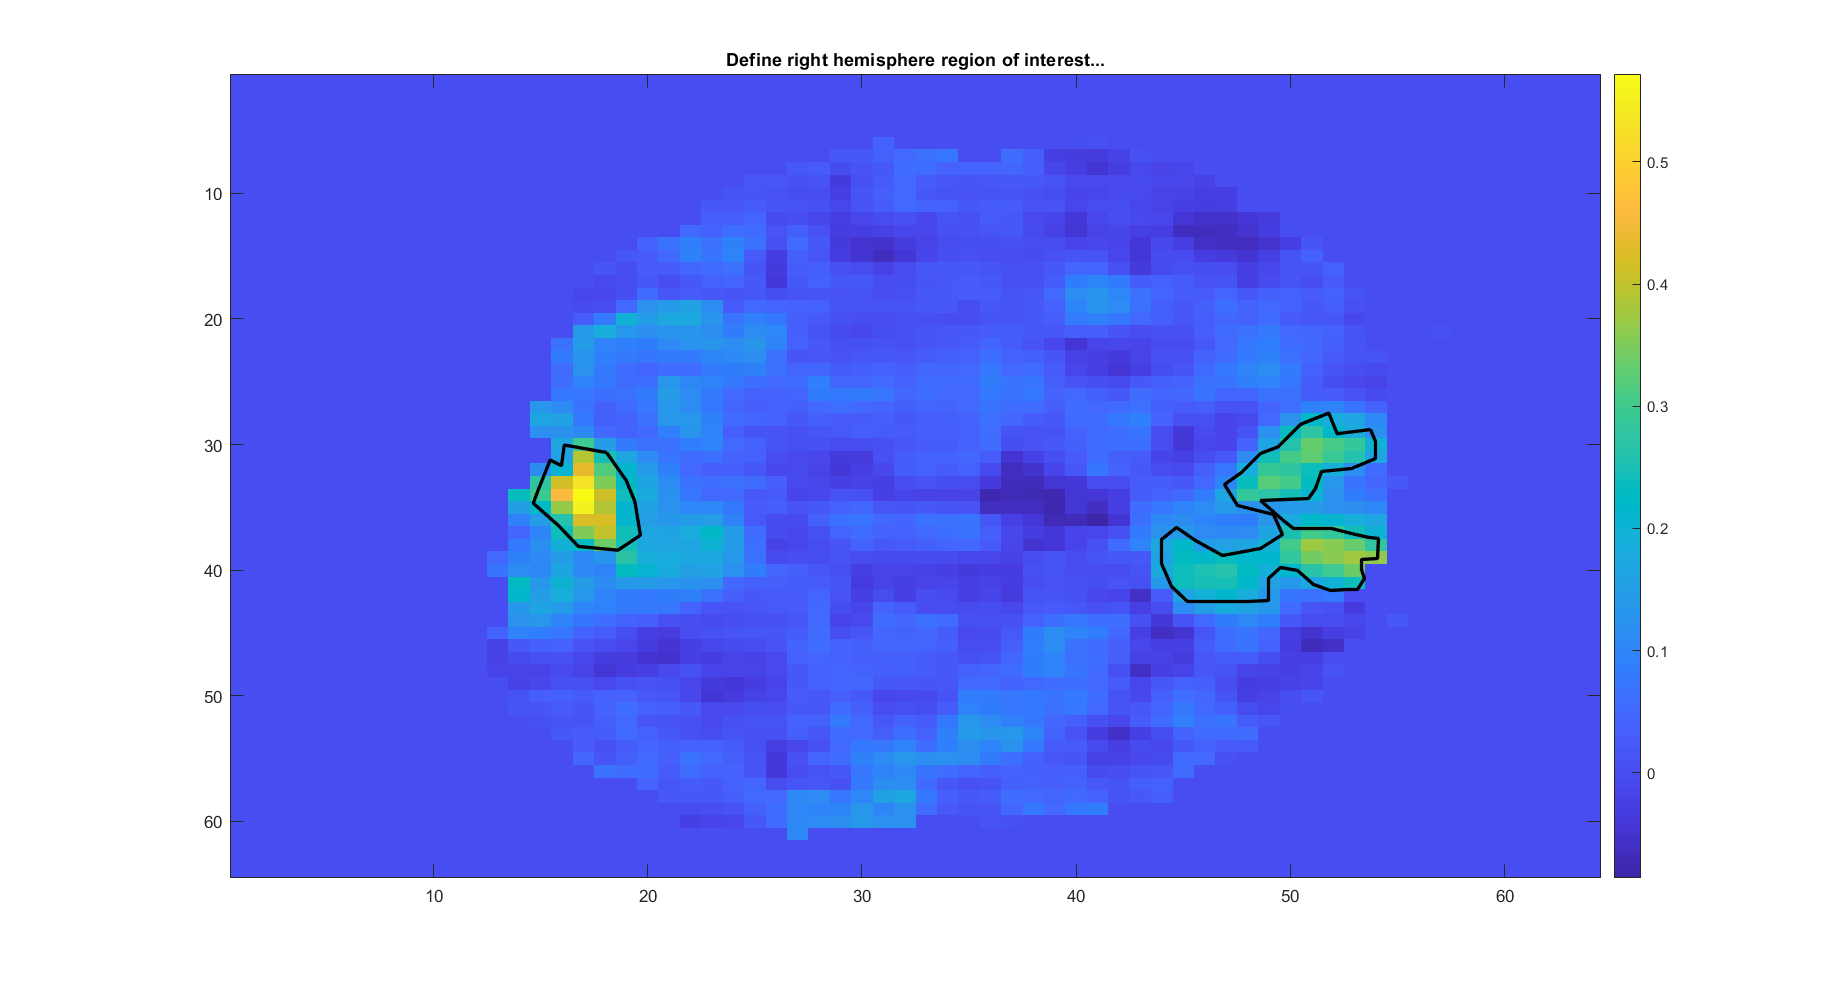

title('Define left hemisphere region of interest...')
[leftRoiMask_m, xLeft_v, yLeft_v] = roipoly;
line(xLeft_v, yLeft_v, 'LineWidth', 2, 'Color', 'k')

title('Define right hemisphere region of interest...')
[rightRoiMask_m, xRight_v, yRight_v] = roipoly;
line(xRight_v, yRight_v, 'LineWidth', 2, 'Color', 'k')

roiMask_m = rightRoiMask_m + leftRoiMask_m;

save('roiMasks.mat', ...
    "leftRoiMask_m","xLeft_v","yLeft_v", ...
    'rightRoiMask_m','xRight_v','yRight_v');

load('roiMasks.mat')

roiSignal_v = zeros(nTimes, 1);
for time = 1:nTimes
    roiSignal_v(time) = sum(sum(roiMask_m.*image2_3d(:, :, time)));    
%     imageSignal_3d(:, :, time) = roiMask_m.*image2_3d(:, :, time);
    if time == 1 
        figure
        imagesc(imageSignal_3d(:, :, time))
        axis image
    end
end

time_v = 1:1:nTimes;
% normalize by L2 norm
roiSignalNormalized = (roiSignal_v - mean(roiSignal_v));
normRoiSignal_v = roiSignalNormalized./norm(roiSignalNormalized,2);
plot(time_v, normSound_v, time_v, normRoiSignal_v)
legend('normSound', 'normRoiSignal')

uniqueSounds = unique(normSound_v)

uniqueSounds =    -0.0680
    0.0680


% Calculate the mean value of roiSignal_v 
% while the stimulus (sound) is on. Call this %meanStim .
% while the stimulus is off. ‘meanRest’. 
meanStim_v = 0;
meanRest_v = 0;
for time = 1:nTimes 
    if normSound_v(time) == uniqueSounds(1)
        meanStim_v = [meanStim_v normRoiSignal_v(time)];
    else 
        meanRest_v = [meanRest_v normRoiSignal_v(time)];
    end
end

meanStim = mean(meanStim_v)

meanStim = -0.0281

meanRest = mean(meanRest_v)

meanRest = 0.0281

% Calculate the standard deviation of roiSignal_v around its mean values 
% (i.e., the standard deviation relative to meanStim during stimulation and relative to meanRest during rest). Using your values of meanStim, meanRest, 
% and noiseStd calculate and display the contrast-to-noise ratio (CNR) of the BOLD measurement.
stdStim = std(meanStim_v)

stdStim = 0.0640

stdRest = std(meanRest_v)

stdRest = 0.0597